## **One Dimensional Wave**

**Yee Algorithm**

This code is modified and built-on from research work that Evans did in the Fall of 2020.

## Admin

clearvars
sympref('FloatingPointOutput',true);

## Section 1: Define Constants and Courant Number

## Given Constants

e0 = 8.86e-12; %permittivity of free space (F/m)

mu0 = 4e-7 .* pi; % permeability of free space (H/m)

er = 1; %permittivity in medium (set to 1 for free space)

mur = 1; %permeability in medium (set to 1 for free space)

e = er .* e0; % e = epsilon (Units F/m)

mu = mur .* mu0; % (Units: H/m)

c = 1./(sqrt(e0*mu0));

Set Courant number (S)

Set $S=\frac{c \Delta t}{\Delta z}$

Then $\Delta t = S\frac{\Delta z}{c}$

S = 0.5; %Courant Number of 1/2 corresponds to the magic time step

c = 3e8; % speed of light in (meters / second)

dz = 5e-3; %space increment in meters as defined in the project part 3 parameters

dt = S .* (dz./c); %


## Section 2: Set up the Wave

Gaussian Pulse "Wave Packet"

sigma = 8 .* dt;  %as defined in Project Part 3

ts = 20 .* dt;



Es = @(t) E0 .* exp(-((t-ts)^2)./(sigma^2));

Create Matrices to hold wave values



L = 1./dz;               %Number of Space Positions so that z(L) = 1

T = 6 .* sigma;          %Number of Time Steps so that over 99% of the Guassian pulse is complete

%Matrices to hold E and H values will be row vectors of length 2L, so that
%each position represents a half step.  

E = zeros(1,2.*L);          %Matrix of electric field values in space (@ t)
Ein = zeros(1,2.*L);        %Temporary Placeholder for the E value input for each space step
Eout = zeros(1,2.*L);       %Temproary placeholder for the E value output for each space step

H = zeros (1,2.*L);         %Matrix of magnetic field values in space (@ t)
Hin = zeros(1,2.*L);        %Temporary placeholder for the H value input for each space step
Hout = zeros (1,2.*L);      %Temporary placeholder for the H value output for each space step

zs = L./4;                  %Define the space point of the Gaussian pulse


## Section 3: Setup Video

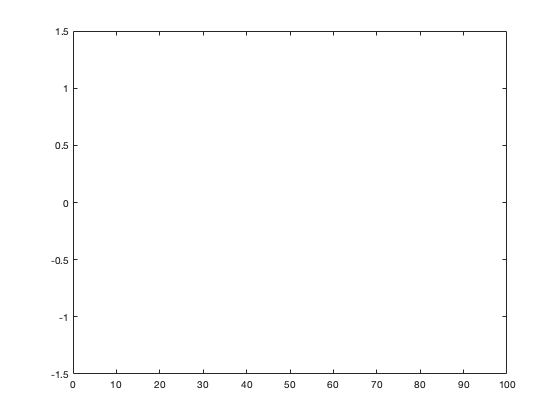

v=VideoWriter("Wave","MPEG-4");
open(v)
plot(2.*L,E(:))
xlim([0 (S/dz)]);
ylim([-1.5 1.5]);
Ylabel="Amplitude";
Xlabel="z";
axis manual
set(gca,"nextplot","replacechildren")
frame=getframe(gcf);

writeVideo(v,frame)


## Section 4: Time step the wave using the Yee Algorithm


for t=1:2.*T                              %Run half time steps (each even step equals a whole step)

    if (-1).^t > 0                        %Calculate the next value of the pulse at z = zs for each whole (even) time step
    E(zs) = Es(t)
    end
    

%     E(1) = H(2);                          % ABCs 
%     E(S) = H(S);
    
    for k=2:(L-1)                     
        Hin(k)= H(k-1);
        Hout(k) = H(k+1);
    end   
        
    for k=2:(L-1)
       
        E(k) =  E(k) - ( S ./ er )  .* ( Hout(k) - Hin(k) );    %calculate E
        
    end
    
%     H(1) = E(1);                          % ABCs 
%     H(S) = E(S-1);
    
    for l=2:(L-1)                       % l = k + 1/2
        Ein(l) = E(l-1);                % these values are populated with E @ t+(1/2)
        Eout(l) = E(l+1);
    end
    
    for l=2:(L-1)
        
        H(l) = H(l) - (S ./ mur ) .* ( Eout(l) - Ein(l) );   %calculate H
        
    end
    
    plot(L.*2,E(:));
    frame=getframe(gcf);
    pause(0.5)
    writeVideo(v,frame)
    
end
close(v)